# Model comparison

% Model description:
% M0: sim_mem_pos1_interaction (full model)
% M1: interaction (without differing trial types but with interaction term)
% M2: sim_mem_pos1 (separating different trial types but without interaction)
% M3: base (no interaction term, trial type not divided)
% M4: notrantion (Use replay all the time, no memory trials)
% M5: null (no replay or memory strategies, totally model-free)

% preparison
clear;clc
resultsdir = '.\analysis_results\';

% modelnames = {'sim_mem_pos1_interaction','interaction','sim_mem_pos1','base','notransition','decreasingcost'};
modelnames = {'M1','M2','M3','M4','M5'}; 

for imodel = 1:length(modelnames)-1
    models{imodel} = load([resultsdir '\' modelnames{imodel} '\Modelresults.mat']);
end

for imodel = 1:length(modelnames)-1
    AICs(:,imodel) = [models{imodel}.Modelresults.AICs(:,1)];
end
AICs(:,imodel+1) = models{imodel}.Modelresults.AICs(:,2); % get the null model results

dAICs = AICs - AICs(:,1);
sAICs = sum(dAICs,1)

sAICs = 1.0e+03 *

         0    0.1021    0.0601    0.1532    1.5219    0.0358    2.1403


ps = exp(-sAICs/2)

ps =     1.0000    0.0000    0.0000    0.0000         0    0.0000         0


## Plot the model comparison

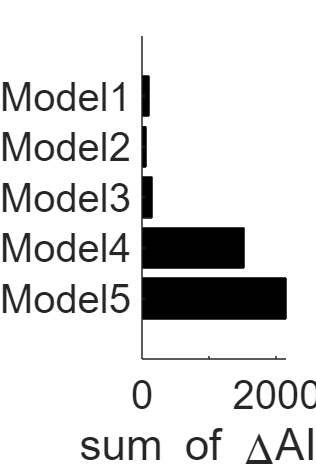

figure('Position',[500 500 400 600]); 
b = bar(sAICs([2:6]),'black');
% camroll(-90);
view([90 90])
% b.BaseValue = 0;
% ylim([-2300 -1900]);
% yticks(-2300:200:-1900)
box off;
xticklabels({'Model1','Model2','Model3','Model4','Model5'});
ylabel('sum of \DeltaAIC')
set(findobj(gcf,'type','axes'),'FontSize',24);

% print('-dpng','-r200',[resultsdir '\AICs_Modelbest_baseline+notransition.png'])

## Description of AIC

meanAIC = mean(AICs,1);
sumAIC = sum(AICs,1)

sumAIC = 1.0e+03 *

   -4.0188   -3.9166   -3.9587   -3.8656   -2.4969   -1.8784   -1.8784


% sumAIC = sum(AICs-AICs(:,end),1)
AICs_demean = AICs - repmat(mean(AICs,2),1,length(modelnames)+1);
meanAIC_demean = mean(AICs_demean,1)

meanAIC_demean =   -26.4842  -23.3898  -24.6639  -21.8430   19.6333   38.3738   38.3738


bestmodel = modelnames{find(meanAIC_demean == min(meanAIC_demean))}

bestmodel = 'sim_mem_pos1_interaction'

sum(AICs_demean)

ans = 1.0e+03 *

   -0.8740   -0.7719   -0.8139   -0.7208    0.6479    1.2663    1.2663


## Do the likelihood ratio test

for imodel = 1:length(modelnames)
    LLss(:,imodel) = [models{imodel}.Modelresults.LLs(:,1)];
    nparas(imodel) = size(models{imodel}.Modelresults.regnamess{1},2);
end
nparas(6) = nparas(6)+1; % because the decreasingcost model has an additional x parameter for cost learning
LLss(:,imodel+1) = models{imodel}.Modelresults.LLs(:,2);
nparas(imodel+1) = 7;

% do the group level likelihood ratio test
nsub=33;
load([resultsdir,'datas.mat']);
for imodel = 1:7
    imodel
    if imodel < 7
        regnames = models{imodel}.Modelresults.regnamess{1};
        idxcol_one = find(strcmp('one',regnames));
        regnames(idxcol_one) = [];
        RTs = [];
        dmss = [];
        subs = [];
        for isub = 1:nsub
            RT = datas{isub}.behRT(find(datas{isub}.behCorrect==1));
            RTs = [RTs;RT];
            dms = models{imodel}.Modelresults.dms{isub};
            dms(:,idxcol_one) = [];
            dmss = [dmss;dms];
            subs = [subs;repelem(isub,length(RT),1)];
        end
    
        tb = array2table([RTs,dmss,subs]);
        tb.Properties.VariableNames = [{'RT'},regnames,{'sub'}];
    %     if ismember('simtrial',regnames) && ismember('memtrial',regnames)
            formula_fix = [regnames{1} '-1'];
            formula_rand = ['(',regnames{1},'-1|sub)'];
    %     else
    %         formula_fix = regnames{1};
    %         formula_rand = ['(1|sub)+(',regnames{1},'-1|sub)'];
    %     end
        for ireg = 2:length(regnames)
            formula_fix = [formula_fix,'+',regnames{ireg}];
            formula_rand = [formula_rand,'+(',regnames{ireg},'-1|sub)'];
        end
        formula = [formula_fix,'+',formula_rand];
        lme = fitlme(tb,['RT~',formula]);
    else
        lme = fitlme(tb,'RT~-1+trial+resp1+resp2+resp3+resp4+resp5+(trial-1|sub)+(resp1-1|sub)+(resp2-1|sub)+(resp3-1|sub)+(resp4-1|sub)+(resp5-1|sub)')
    end
    LLs_group(imodel) = lme.LogLikelihood;
end

imodel = 1

imodel = 2

imodel = 3

imodel = 4

imodel = 5

imodel = 6

imodel = 7

lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations            7478
    Fixed effects coefficients           6
    Random effects coefficients        198
    Covariance parameters                7

Formula:
    RT ~ trial + resp1 + resp2 + resp3 + resp4 + resp5 + (trial | sub) + (resp1 | sub) + (resp2 | sub) + (resp3 | sub) + (resp4 | sub) + (resp5 | sub)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    21004    21094    -10489           20978   

Fixed effects coefficients (95% CIs):
    Name             Estimate    SE          tStat      DF      pValue    Lower       Upper   
    {'trial'}        -0.37009    0.018291    -20.233    7472    0         -0.40594    -0.33423
    {'resp1'}          4.2493    0.089754     47.344    7472    0           4.0734      4.4253
    {'resp2'}          4.2645    0.088804     48.021    7472    0           

for imodel = 1:7
    for jmodel = 1:7
        if nparas(imodel)-nparas(jmodel) > 0
            [~,pValue,stat,cValue] = lratiotest(LLs_group(imodel),LLs_group(jmodel),nparas(imodel)-nparas(jmodel));
            pValues(imodel,jmodel) = pValue;
        else
            pValues(imodel,jmodel) = exp(-0.5*(sumAIC(jmodel) - sumAIC(imodel)));
        end
    end
end

pValues

pValues = 1.0e+297 *

    0.0000    0.0000    0.0000         0         0         0         0
    0.0000    0.0000    0.0000    0.0000         0         0         0
    0.0000    0.0000    0.0000    0.0000         0         0         0
    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
       Inf       Inf       Inf    1.6334    0.0000    0.0000         0
    0.0000    0.0000    0.0000    0.0000         0    0.0000         0
       Inf       Inf       Inf       Inf    0.0000    0.0000    0.0000
